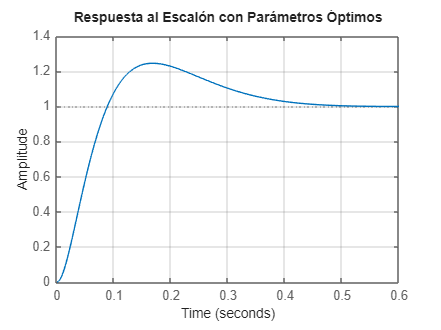

clc; clear; close all;

%% === Definición de la funcion ===
s = tf('s');
K = 2652.28/23;
p = 64.986;
G = K / (s * (s + p));

%% === Función objetivo para optimización ===
objective_PID = @(x) compute_cost(x, G, p, K);

%% === Optimización ===
x0 = [1, 0.05, 0.02, 0.01]; % [Kp, tau_I, tau_D1, tau_D2]
x_opt = fminsearch(objective_PID, x0);

%% === Parámetros óptimos ===
Kp_opt     = x_opt(1);
tau_I_opt  = x_opt(2);
tau_D1_opt = x_opt(3);
tau_D2_opt = x_opt(4);
tau_Dtilde_opt = tau_D1_opt + tau_D2_opt;

%% === Sistema óptimo ===
numerador_PID_opt = K * Kp_opt * tau_D1_opt * (s^2 + s / tau_D1_opt + 1 / (tau_D1_opt * tau_I_opt));
denominador_PID_opt = s^2 * (s + p) + K * Kp_opt * tau_Dtilde_opt * (s^2 + s / tau_Dtilde_opt + 1 / (tau_Dtilde_opt * tau_I_opt));
T_opt = numerador_PID_opt / denominador_PID_opt;

%% === Respuesta al escalón y métricas ===
figure
step(T_opt)
grid on
title('Respuesta al Escalón con Parámetros Óptimos')



info_opt = stepinfo(T_opt);

fprintf('\n=== Parámetros Óptimos ===\n');


=== Parámetros Óptimos ===


fprintf('Kp     = %.4f\n', Kp_opt);

Kp     = 10.0290


fprintf('tau_I  = %.4f\n', tau_I_opt);

tau_I  = 0.1506


fprintf('tau_D1 = %.4f\n', tau_D1_opt);

tau_D1 = 0.0000


fprintf('tau_D2 = %.4f\n', tau_D2_opt);

tau_D2 = 0.0000



fprintf('\n=== Métricas de Desempeño ===\n');


=== Métricas de Desempeño ===


fprintf('Overshoot     = %.2f%%\n', info_opt.Overshoot);

Overshoot     = 24.49%


fprintf('Rise Time     = %.4f s\n', info_opt.RiseTime);

Rise Time     = 0.0616 s


fprintf('Settling Time = %.4f s\n', info_opt.SettlingTime);

Settling Time = 0.4178 s


fprintf('Peak Time     = %.4f s\n', info_opt.PeakTime);

Peak Time     = 0.1680 s



%% === Función de costo ===
function cost = compute_cost(x, G, p, K)
    Kp = x(1);
    tau_I = x(2);
    tau_D1 = x(3);
    tau_D2 = x(4);

    if any(x <= 0)  % evitar valores negativos o cero
        cost = 1e6;
        return;
    end

    tau_Dtilde = tau_D1 + tau_D2;
    s = tf('s');

    num = K * Kp * tau_D1 * (s^2 + s / tau_D1 + 1 / (tau_D1 * tau_I));
    den = s^2 * (s + p) + K * Kp * tau_Dtilde * (s^2 + s / tau_Dtilde + 1 / (tau_Dtilde * tau_I));
    T = num / den;

    info = stepinfo(T, 'SettlingTimeThreshold', 0.02);

    if isempty(info) || isnan(info.Overshoot)
        cost = 1e6;
        return;
    end

    cost = 0;
    % Penalización por overshoot fuera del rango [5%, 12%]
    if info.Overshoot < 5 || info.Overshoot > 12
        cost = cost + 1000 * abs(info.Overshoot - 8.5);
    end
    % Penalización por tiempo de establecimiento > 0.45s
    if info.SettlingTime > 0.45
        cost = cost + 1000 * (info.SettlingTime - 0.45);
    end
    % Penalización por tiempo de subida > 0.3s
    if info.RiseTime > 0.3
        cost = cost + 1000 * (info.RiseTime - 0.3);
    end
end